load('1-CCRN-1-cat_Ham.mat')

$$Ham = \frac{369\,{\mathrm{e}}^{p_{1}}}{2500}+q_{3}\,\left(\frac{103\,{\mathrm{e}}^{p_{1}+p_{2}-p_{3}}}{50}-\frac{103}{50}\right)+q_{1}\,\left({\mathrm{e}}^{-p_{1}}-1\right)+q_{2}\,\left(\frac{29\,{\mathrm{e}}^{p_{1}}}{10}-\frac{29}{10}\right)+{q_{1}}^{2}\,\left({\mathrm{e}}^{p_{2}-2\,p_{1}}-1\right)+q_{2}\,\left(\frac{103\,{\mathrm{e}}^{2\,p_{1}-p_{2}}}{50}-\frac{103}{50}\right)+q_{1}\,q_{2}\,\left({\mathrm{e}}^{p_{3}-p_{2}-p_{1}}-1\right)+q_{1}\,q_{2}\,\left({\mathrm{e}}^{-p_{1}}-1\right)-\frac{369}{2500}$$

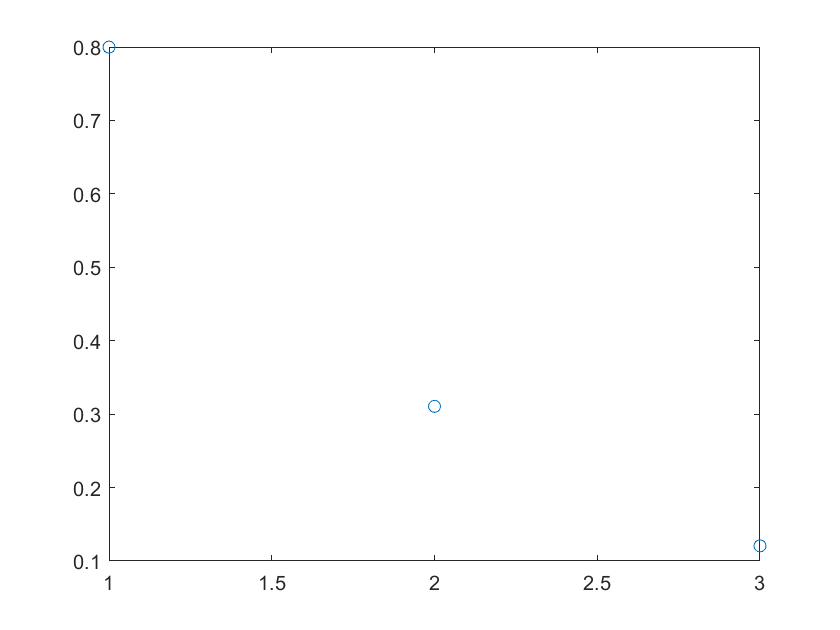

clust = 1:3;
figure()
plot(clust,pos_root_arr(1,:),'o')


figure()
%log_imp = -log(N);
plot(bin_pos,(rplus_val-rmin_val)/2500,'m--','Linewidth',0.8)
hold on
plot(bin_pos,(NEP_val-min(NEP_val)),'b','LineWidth',1.8)
yline(0,'-.','Linewidth',0.7,'color',[.7 .7 .7])
%scatter(roots,zeros(size(roots)),50,'ko')
%scatter(stab,zeros(size(stab)),50,'kx')
%scatter(rep,zeros(size(rep)),50,'k.')
%plot(bin_pos,V*(NEP_val-min(NEP_val)),'b','LineWidth',1.4)
hold off
ylim([-0.005,0.01])
xticks(floor(bin_pos(1)):1:ceil(bin_pos(end)))
legend('MAK','NEP','interpreter','latex',"FontSize",15,'location','best')
%legend('NEP','interpreter','latex',"FontSize",15)
%ylabel('Det. Velocity $\dot{q}=\partial H/ \partial p|_{p=0}$','interpreter','latex',"FontSize",15)
ylabel('NEP','interpreter','latex',"FontSize",15)
xlabel('q','interpreter','latex',"FontSize",15)
tit_str = "$\{\underline{q}\}$ = \{";
for i = 1:size(roots,2)-1
    tit_str = tit_str + string(roots(1,i)) + ", ";
end
tit_str = tit_str + string(roots(1,end)) + "\}"

title(tit_str,'interpreter','latex',"FontSize",15)
set(gca,'FontName','cmr12')
saveas(gcf,savename)
